##  Coarse Frame Search Using the Frequency Domain Representation

Author: Michel Barbeau, Carleton University

Draft version: December 30, 2018

### Intro

This MATLAB live script describes the coarse search for frames. This script reads a file with the ".c2" extension. The c2-format is a baseband representation of channel data, with the in-phase and quadrature. In the representation, the script finds frequencies that potentially contain frames. Each frame comprises 162 channel symbols, which encode 50 information bits. Convolutional Forward Error Correction (FEC) is used, with a constraint of 32  and a rate of $1/2$. Convolutional  encoding of the information bits yields 162 bits. They are interleaved with 162 synchronization bits $s_i$ ($i=1,\ldots,162$):

clear;
% synchronization bits
s = [1 1 0 0 0 0 0 0 1 0 0 0 1 1 1 0 0 0 1 0 0 1 0 1 1 1 1 0 0 0 0 0 0 0 1 0 0 1 0 1 ...
     0 0 0 0 0 0 1 0 1 1 0 0 1 1 0 1 0 0 0 1 1 0 1 0 0 0 0 1 1 0 1 0 1 0 1 0 1 0 0 1 ...
     0 0 1 0 1 1 0 0 0 1 1 0 1 0 1 0 0 0 1 0 0 0 0 0 1 0 0 1 0 0 1 1 1 0 1 1 0 0 1 1 ...
     0 1 0 0 0 1 1 1 0 0 0 0 0 1 0 1 0 0 1 1 0 0 0 0 0 0 0 1 1 0 1 0 1 1 0 0 0 1 1 0 ...
     0 0];

Every data bit is paired with a synchronization bit. Each pair makes a channel symbol. Modulation is four-tone Multiple Frequency-Shift Keying (MFSK) at 1.46 baud ($375/256$). The complex modulation envelope frequencies are -2.2, -0.7, 0.7 and 2.2 Hertz, corresponding to channel symbols 0, 1, 2 and 3. The signal bandwidth is therefore 4.4 Hertz. The transmission time of a frame is 111 seconds.

### Reading a file with the .c2 extension

% name of ".c2" file
FileName = '150426_0918.c2';
fileID = fopen(FileName,'r');

The following three parameters (file name, type and frequency) are read but not interpreted.

% read file name (14 characters)
fname=fread(fileID,[1 14],'char');
% read WSPR type (integer) 2="2 minute mode"
type=fread(fileID,[1 1],'int');
% read frequency (double)
dfreq=fread(fileID,[1 1],'double');

The content of the file represents 120 seconds of signal samples that have been buffered, termed the *two minute mode*. The sampling rate ($f_s$) is 375 samples per second (sps). Hence there are $n=375 \cdot 120=45,000$ complex samples (in-phase and quadrature) read. Let $x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_{n-1}$ represent the discrete complex samples of two-minute channel data.

n=45000; % number of sambles (120 seconds of channel data)
fs=375; % sampling frequency
% read data (float)
buffer=fread(fileID,[2 n],'float');
% close the ".c2" file
fclose(fileID);

The in-phase and quadrature signals are respectively assigned to the MATLAB variables I and Q.

% in-phase
I=buffer(1,:);
% quadrature
Q=buffer(2,:);

We have that every $x_i =\mathrm{I}\left\lbrack i+1\right\rbrack +\mathit{jQ}\left\lbrack i+1\right\rbrack$. Each channel symbol is represented by 256 samples. A frame consists of 256 samples per symbol times 162 channel symbols, i.e., 41,472 samples.

### Ploting the data in the frequency domain

This part builds and plot the frequency domain representation. The representation decomposes the whole 120 second period into components of different frequencies. A stepped-frequency domain representation is constructed. Steps are counted in half symbol periods. At each step, a sub-window corresponding to the duration of two symbols is decomposed into component frequencies. Each symbol being represented by 256 samples, a half symbol consists of 128 samples. Therefore, the number of FFTs is

$nffts=\left\lfloor \frac{n \mbox{ samples}}{ 128 \mbox{ samples per half symbol}} \right\rfloor - 3 \mbox = 348 \mbox{ FFTs}$.

The subtrahend 3 is present because calculations of windowed FFTs stop before the third to last half-sample.

% number of samples per half symbol
hs = 128;
% number of FFTs
nffts=floor(n/hs)-3;

The size of each FFT (variable N) is

$N = 2 \mbox{ symbols} \cdot 256 \mbox{ samples/symbol} = 512 \mbox{ bins}$.

% FFT size
N=512; % bins

Used together with the FFT, the windowing function is


$$w(t) = \sin\left(\frac{\pi}{512} \cdot t\right), \mbox{ t=0,...,N-1.}$$


It is a half-sine wave cycle, in N steps.

% windowing function
w=sin([0:(N-1)].*pi/N);

Every FFT coefficient  is defined as

$X_{m,k}
=
\sum_{t=0}^{N-1}
	x_{128m+t} \cdot 
	w(t) \cdot
	e^{-\sqrt{-1} \cdot 2 \pi k t/N}$.  

The FFT window index $m\;$is in the range $0,\ldotp \ldotp \ldotp ,\mathrm{nffts}-1$. It represents the relative amplitude, and phase, of frequency

$\frac{k \cdot f_s \mbox{ sps}}{N \mbox{ samples}} \mbox{ Hertz}$.

From frequency-bin-to-frequency-bin, there is an offset $\Delta f$ of $375/512=0.73$ Hertz. At 375 sps and according tothe Nyquist criterion, the frequency range of each FFT is  $\pm 187$ Hertz. The coefficient index $k$ is in the range $\pm187 \cdot N / f_s = \pm 255$. In the frequency domain, every two-minute time interval is represented by the following matrix:


$$X=
\left( \matrix{ X_{0,-256}     & \ldots & X_{0,0}    & \ldots & X_{0,255} \cr
\vdots              & \cdots & \vdots      & \cdots & \vdots \cr
X_{nffts-1,-256}  & \ldots & X_{nffts-1,0} & \ldots & X_{nffts-1,255} } \right)$$
 

In MATLAB:

% coefficient array
X=[];
for k=1:nffts
    % FFT over a two-symbol interval
    k=(k-1)*hs+1;
    % windowing function
    Iw=I(k:k+N-1).*w;
    Qw=Q(k:k+N-1).*w;
    Y=fft(complex(Iw,Qw),N)/N;
    Z=[Y(1,N/2+1:N),Y(1,1:N/2)];
    X=[X ; Z];
end;

 Note that the array items represented  by variable Y(1,N/2+1:N) correspond to the negative frequencies


$$X_{m,-N/2} , \ldots, X_{m,-1} $$


while the array items represented by variable Y(1,1:N/2) correspond to the positive frequencies

$ X_{m,0}  \ldots, X_{m,N/2-1} $.

They are re-ordered into MATLAB variable Z from negative to positive frequencies. The frequency domain representation is used for a coarse signal search. The procedure looks for candidates in the frequency domain, i.e., columns in the matrix where there is a local  Signal-to-Noise Ratio (SNR) maximum. We plot on a dB scale, the manitude of the signal at zero Hertz, plus-minus the 56 adjacent frequencies.

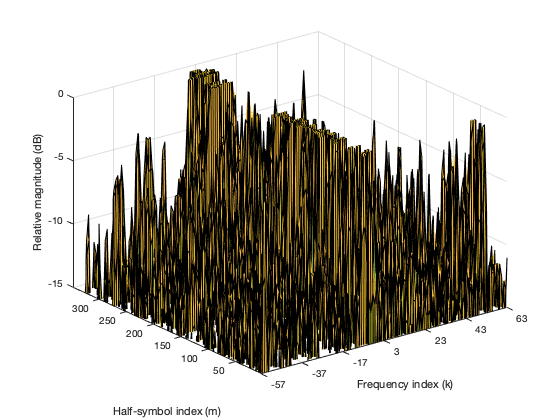

figure;
[m,k]=meshgrid(1:N,1:nffts);
surfc(m,k,db(abs(X(1:nffts,1:N))));
grid on;
xlabel('Frequency index (k)');
xlim([200 320]);
set(gca,'XTick',200:20:320)
set(gca,'XTickLabel',200-257:20:320-257)
zlim([-15 0]);
ylabel('Half-symbol index (m)');
zlabel('Relative magnitude (dB)');

The vertical axis (Z) provides the relative magnitude of the signal (in dB) as a function of time (counted in half-symbol), axis X, and frequency (in units of 0.73 Hertz). The indices of the negative frequencies are N/2+1 to N. The indices of the positive frequencies are 1 to N/2. This plots reveals the presence of a data signal at zero Hertz.

### Finding frequencies of candidate signals

We first store into variable W the complex magnitude at each frequency bin, a calculation corresponding to the following equation $W_{i,j} =\left|X_{i,j} \right|$. We have that the variable$W_{i,j\;}$denote the magnitude of the signal at indices $i$ and $j$, in linear form.

W=abs(X);

Next, we compute average magnitude of each bin:

M=mean(W,1);

Variable M represents the average signal magnitude as a function of frequency. The magnitude is smoothed taking, for each frequency, the sum of the magnitudes of signals at three adjacent frequencies, resulting into $N-\left(2\cdot 3\right)=506$ bins. This results into the relative magnitude of the signal over a bandwidth of $6\cdot 0\ldotp 73=4\ldotp 38$ Hertz:

% smoothing
SM=zeros(1,506);
for k=1:length(SM)
    for j=-3:1:3
        SM(k)=SM(k)+M(k+3+j);
    end;
end;

The smoothed average magnitude level are sorted in ascending order:

SSM=sort(SM);

The following heuristic is used. The 150-th component (30% of 506) is chosen as the noise reference level:

noise_level=SSM(150);

A minimum reference Signal-to-Noise Ratio (SNR) is chosens, -7 dB,  in linear form it is 

$min_{SNR} = 10^{-0.7}$.

min_snr = 10.0^(-7.0/10.0);

The frequency domain representation is normalized with respect to the reference noise level.

for j=1:length(SM)
    SM(j)=SM(j)/noise_level - 1.0;
    if (SM(j) < min_snr) 
        SM(j)=0.1*min_snr;
    end
end;

Everything below the ${\mathrm{min}}_{\mathrm{SNR}}$ is scaled downnn to value ${0\ldotp 1\cdot \min }_{\textrm{SNR}}$. The following plots the normalized smoothed average power versus noise rerefence level:

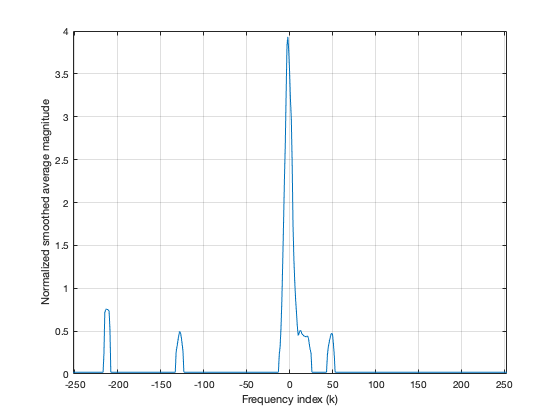

figure;
plot([-(length(SM)/2-1):1:-1 0 1:length(SM)/2],SM);
grid on;
xlim([-(length(SM)/2-1) length(SM)/2]);
xlabel('Frequency index (k)');
ylabel('Normalized smoothed average magnitude');

This result into the following plot. It reveals the presence of frequencies with signal peaks with potential frames. This will be confirmed in the sequel of the search.

After that manipulation, indices with normalized smooothed average magnitude above  $\min_{\textrm{SNR}}$ become indices of candidate frequencies.

candidate=[];
for k=1:length(SM)
    if(SM(k)>min_snr)
        candidate = [candidate struct('index',k-(length(SM)/2-1)-1,'SNR',SM(k))];
    end;
end;
fprintf('The number of candidates is %d\n', length(candidate));

The number of candidates is 64


fprintf('[index 6-Hz-SNR(dB)]\n');

[index 6-Hz-SNR(dB)]


for k=1:length(candidate)
    fprintf('[%d %2.2f] ', candidate(k).index, db(candidate(k).SNR));
end

[-216 -12.50] [-215 -2.91] [-214 -2.53] [-213 -2.39] [-212 -2.47] [-211 -2.51] [-210 -2.70] [-209 -5.74] [-132 -11.73] [-131 -9.99] [-130 -8.31] [-129 -7.03] [-128 -6.07] [-127 -6.32] [-126 -7.35] [-125 -9.12] [-124 -11.60] [-12 -12.90] [-11 -9.89] [-10 -5.50] [-9 -1.45] [-8 2.20] [-7 4.92] [-6 7.09] [-5 8.53] [-4 10.29] [-3 11.67] [-2 11.89] [-1 11.53] [0 10.95] [1 10.11] [2 9.49] [3 7.86] [4 4.81] [5 2.58] [6 0.69] [7 -1.16] [8 -2.82] [9 -5.04] [10 -6.96] [11 -6.50] [12 -5.94] [13 -5.91] [14 -6.43] [15 -6.72] [16 -6.87] [17 -7.13] [18 -7.14] [19 -7.23] [20 -7.22] [21 -7.04] [22 -7.66] [23 -9.21] [24 -10.94] [25 -12.39] [44 -13.25] [45 -10.15] [46 -8.73] [47 -7.65] [48 -6.79] [49 -6.46] [50 -6.72] [51 -8.98] [52 -13.16] 

fprintf('\n');

Every candidate is further examined for the presence of a frame.

The receiver has the capability to search for frames with possibly linearly or nonlinearly drifting carriers. Using the corresponding candidate frequencies as carriers, refined signal paths are searched. A path is defined by a signal tracking function


$$f_{\theta}: \{ 0 \ldots nffts-1 \} \mapsto \{ -256\ldots  0 \ldots 255 \}$$


where $\theta \;$is a parameter of function$f$. Let $\Phi$ denote the set of all instances of such signal tracking functions (assume it is finite size, i.e., there is a finite number of functions and the domains of their parameters are finite). There are three cases. Firstly, the tracking of a signal not subject to the Doppler effect, i.e., its frequency is not drifting, is represented by a constant function $f\left(i\right)=c,$ where $i\;$is the half-symbol index and $c$ is the carrier frequency. Secondly, the tracking of a signal subject to a Doppler effect such that the carrier frequency is drifting linearly, is represented by function $f_{\delta} (i) = c + \delta i$. The parameter $\delta$ represents the quantity of frequency drift per half symbol. Thirdly, tracking of a signal  subject to a Doppler effect such that the carrier frequency is drifting nonlinearly, is represented by an arbitrary function.

### Testing correlation with synchronization bits and resolving timing offset

In a window of two minutes, a whole 162-symbol frames may start anywhere form the beginning of the window to a maximum delay form the start, counted in half-symbols, of


$$348 \mbox{ half-symbols/window}- 2\cdot 162\mbox{ half-symbols/frame} = 24 \mbox{ half-symbols}.$$
  

max_offset=348-2*162; % half symbols

For the signal tracking function $f_{\theta}$, the timing offset $\tau$ is the value in the range $0,\ldots,27$ that maximizes the sum:


$$\sum_{i=1}^{162} 
(2 s_i - 1)
\left[
\frac{
	(W_{2i+\tau,f_{\theta}(2i+\tau)-4} + W_{2i+\tau,f_{\theta}(2i+\tau)+1}) - (W_{2i+\tau,f_{\theta}(2i+\tau)-1} + W_{i,f_{\theta}(2i+\tau)+4})
}{
	\displaystyle\sum_{k=-4, -1, 1, 4}
	\vert W_{2i+\tau,f_{\theta}(i)+k)} \vert
}
\right]$$


The summation measures the correlation of the spectrum magnitude around frequency $f_{\theta}$ with the synchronization bit-string $s$. The multiplicand $2s_i -1$maps the synchronization bit $s_i$ which is 0 or 1, to value -1 or 1. The term


$$W_{2i+\tau,f_{\theta}(2i+\tau)-4} + W_{2i+\tau,f_{\theta}(2i+\tau)+1}$$


is the sum of the magnitudes at the frequencies of synchronization bit value 1, while the term


$$W_{2i+\tau,f_{\theta}(2i+\tau)-1} + W_{2i+\tau,f_{\theta}(2i+\tau)+4}$$


is the sum of the magnitudes at the frequencies of synchronization bit value 0. The denominator represents the sum of all magnitudes around frequency $f_{\theta}(i)$.

% for every candidate signal, determine the timing offset
timing = [];
for k=1:length(candidate)
    % frequency index (-256..0..255 mapped to 1..512, a MATLAB array index)
    g = candidate(k).index + 257; % no drift assumed
    offset = 0; max = 0;
    % find correlation peak vs timing offset
    for tau=0:max_offset
        % compute correlation
        corr = 0;
        for i=1:162
            corr=corr + (...
                (2*s(i)-1)*...
                ( (W(2*i+tau,g-4)+W(2*i+tau,g+1))-(W(2*i+tau,g-1)+W(2*i+tau,g+4)) )/...
                (W(2*i+tau,g-4)+W(2*i+tau,g-1)+W(2*i+tau,g+1)+W(2*i+tau,g+4)) );
        end
        % is it a peak?
        if corr>max
            max = corr;
            offset = tau;
        end
    end
    timing = [timing...
        struct('index',candidate(k).index,'SNR',candidate(k).SNR,'offset',offset)];
end
fprintf('[index 6-Hz-SNR(dB) offset(half-symbols)]\n');

[index 6-Hz-SNR(dB) offset(half-symbols)]


for k=1:length(timing)
   fprintf('[%d %2.2f %d] ', timing(k).index, db(timing(k).SNR), timing(k).offset);
end

[-216 -12.50 4] [-215 -2.91 0] [-214 -2.53 0] [-213 -2.39 21] [-212 -2.47 18] [-211 -2.51 19] [-210 -2.70 0] [-209 -5.74 0] [-132 -11.73 13] [-131 -9.99 12] [-130 -8.31 10] [-129 -7.03 3] [-128 -6.07 3] [-127 -6.32 19] [-126 -7.35 12] [-125 -9.12 3] [-124 -11.60 2] [-12 -12.90 21] [-11 -9.89 10] [-10 -5.50 8] [-9 -1.45 23] [-8 2.20 3] [-7 4.92 4] [-6 7.09 5] [-5 8.53 14] [-4 10.29 0] [-3 11.67 1] [-2 11.89 22] [-1 11.53 16] [0 10.95 17] [1 10.11 0] [2 9.49 0] [3 7.86 0] [4 4.81 22] [5 2.58 17] [6 0.69 2] [7 -1.16 3] [8 -2.82 10] [9 -5.04 10] [10 -6.96 1] [11 -6.50 21] [12 -5.94 15] [13 -5.91 10] [14 -6.43 1] [15 -6.72 1] [16 -6.87 6] [17 -7.13 17] [18 -7.14 10] [19 -7.23 15] [20 -7.22 1] [21 -7.04 4] [22 -7.66 18] [23 -9.21 22] [24 -10.94 15] [25 -12.39 0] [44 -13.25 8] [45 -10.15 14] [46 -8.73 0] [47 -7.65 2] [48 -6.79 7] [49 -6.46 20] [50 -6.72 21] [51 -8.98 14] [52 -13.16 7] 

fprintf('\n');

### Calculating the soft symbols (to be revised)

The power at synchronization bits is relativized to all the power at the candidate frequency.

For each signal tracking function $f_{\theta}$ , over a symbol interval of length $T$, the power is summed to obtain the energy$\left(f=-2\ldotp 2,-0\ldotp 7,0\ldotp 7,2\ldotp 2\right)$:


$$r_{i,f} + \sqrt{-1} q_{i,f}
=
\sum_{t=iT+\tau}^{(i+1)T+\tau}
x_t \cdot e^{-\sqrt{-1} 2 \pi [ f_{\theta}(t)\cdot 0.73 +f ]  t} $$


Which is mapped to a magnitude

$P_{i,f}  = \vert r_{i,f} + \sqrt{-1} q_{i,f} \vert$.

The four magnitudes $P_{i,f}$are used to calculate soft symbols. A soft symbol represents a value and its quality. Receive quality metrics are associated with the symbols. This information is used in the decoding process. The most likely symbols are selected first. A de-interleaving procedure reorders the 162 data soft symbols. The resulting 162 soft symbols are passed to a FEC decoder.